# Laborator 10

## 5 Probleme


$$\int_0^{\frac{\pi}{2}} cos(x)dx = 1$$


clear;
format long;
syms x_sym;
f = cos(x_sym);
fdd = diff(f, x_sym, 2)

$$fdd = -\cos\left(x_{\mathrm{sym}}\right)$$

fn = matlabFunction(f);
fndd = matlabFunction(fdd);
a = 0;
b = pi/2;
n = 20;
x_plot = linspace(a, b, n);
y_plot = fn(x_plot);
integral(fn, a, b)

ans =    1.000000000000000


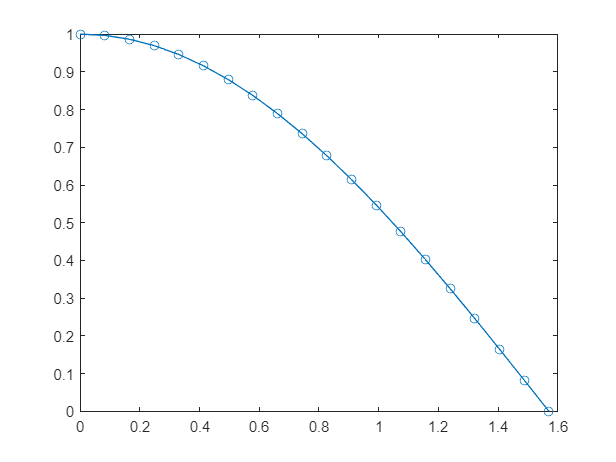

plot(x_plot, y_plot, 'o-');

### 5.1

#### a) Formula repetata a trapezului

integrala_repetata_trapez = MetRepetataTrapez(a, b, fn, fndd, n/2)

integrala_repetata_trapez =    0.999688065811311


#### b) Formula dreptunghiurilor

integrala_dreptunghi = MetRepetataDreptunghi(a, b, fn, fndd, n)

integrala_dreptunghi =    1.000038932265184


#### c) Formula repetata a lui Simpson

integrala_simpson = MetRepetataSimpson(a, b, fn, n)

integrala_simpson =    1.077511083237610


#### 5.2

#### a) Formula trapezoid

Aria unui trapez = $A = (a + b) / 2 * h$, a,b = f(i), f(i+1), h = (b-a)/n

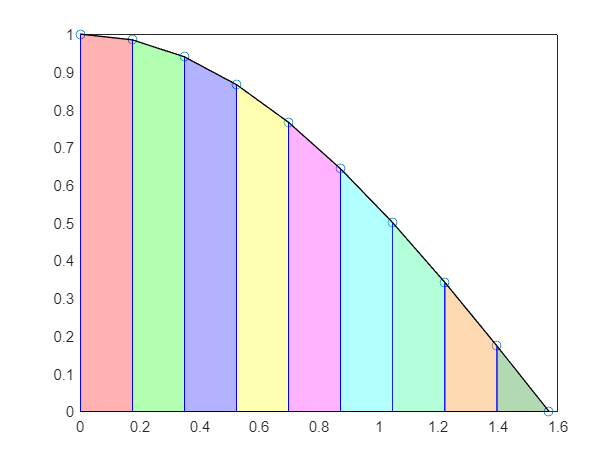

clear;
format long;
syms x_sym;
f = cos(x_sym);
fdd = diff(f, x_sym, 2);
fn = matlabFunction(f);
fndd = matlabFunction(fdd);
a = 0;
b = pi/2;
n = 10;
x_plot = linspace(a, b, n);
y_plot = fn(x_plot);
figure;
clf;
plot(x_plot, y_plot, 'o-');
hold on;
colors = {[1, 0, 0], [0, 1, 0], [0, 0, 1], [1, 1, 0], [1, 0, 1], [0, 1, 1], [0, 1, 0.5], [1, 0.5, 0], [0, 0.5, 0]}; % Red, Green, Blue, Yellow
transparency = 0.3;
for i = 1:length(x_plot)-1
    % Define the vertices of the polygon to fill
    x_fill = [x_plot(i), x_plot(i), x_plot(i+1), x_plot(i+1)];
    y_fill = [0, y_plot(i), y_plot(i+1), 0];
    
    % Use the fill function to create the colored area
    fill(x_fill, y_fill, colors{i}, 'FaceAlpha', transparency);
end

for i = 1:length(x_plot)
    plot([x_plot(i), x_plot(i)], [0, y_plot(i)], 'b-'); % 'b-' specifies blue solid lines
end

#### b) Vizualizare Simpson

Simpson estimeaza integrala unei functii prin calcularea exacta a integralei a polinomului Lagrange pt acea functie initiala prin punctele echidistante

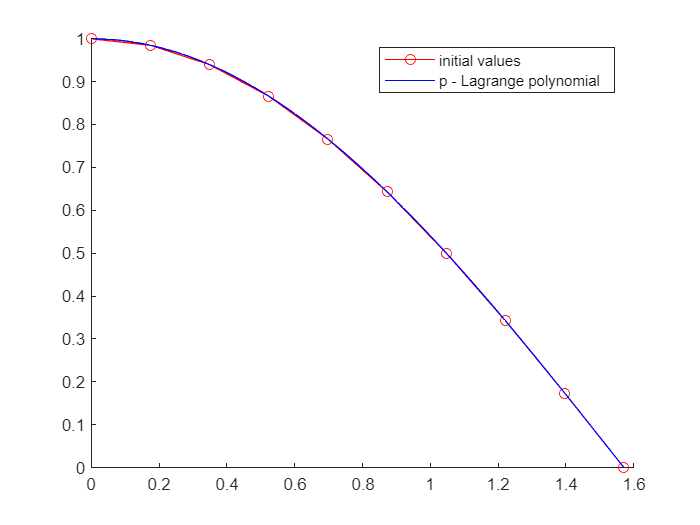

[p, l] = LagrangeInterpolation(x_plot, y_plot);
xx = linspace(a, b, 100);
yy_Lagrange = p(xx);
figure;
clf;
hold on;
plot(x_plot, y_plot, 'ro-')
plot(xx, yy_Lagrange, 'b-');
legend('initial values', 'p - Lagrange polynomial', 'Location', 'best');

### 5.4 - Romberg Algorithm

clear;
format long;
syms x_sym;
f = cos(x_sym);

fn = matlabFunction(f);

a = 0;
b = pi/2;
n = 20;
x_plot = linspace(a, b, n);
y_plot = fn(x_plot);
integral(fn, a, b)

ans =    1.000000000000000


figure;
clf;
plot(x_plot, y_plot, 'o-');

error = 1e-3;
max_n = 15;
[R, i, found] = Romberg(fn, a, b, error, max_n);

if found == 0
    fprintf("for error = %.15f\n", error);
    fprintf("couldn't find good value for max n = %d\nfound: %.15f", n, R(n+1,n+1));
else
    fprintf("for max_n = %d\nfound best value at n = %d\nvalue = %.15f\n", max_n, i, R(i,i));
end

for max_n = 15
found best value at n = 4
value = 1.000000008144021


### 5.3 Cuadraturi Adaptive

#### a) Cuadratura adaptiva pt formula repetata a lui Simpson

adaptquad(a, b, @MetRepetataSimpson, fn, fndd, 1e-5)

ans =    1.000068952953420


#### b) Cuadratura adaptiva pt formula repetata a trapezelor

adaptquad(a, b, @MetRepetataTrapez, fn, fndd, 1e-5)

ans =    0.999994695343433


#### c) Cuadratura adaptiva pt formula repetata a dreptunghiurilor

adaptquad(a, b, @MetRepetataDreptunghi, fn, fndd, 1e-5)

ans =    1.000002652657429


### 5.5 Adquad

Q = adquad(a, b, fn, 1e-5)

Q =    0.999999998095422


## 6 Probleme Practice

### 6.1 Formule Newton-Cotes inchise pt n noduri

NCC = NewtonCotesClosed(a, b, n, fn, x_arr)

NCC =    0.999999999999996


### 6.2 Testare pt functii a caror primitiva nu este exprimabile prin fct elem si comparat cu quad(), integral()


$$\int_1^2e^{x^2}dx \\ \int_0^4e^{-3x}sin4xdx$$


clear;
syms x_sym;
% f = exp(x_sym .^ 2);
f = exp(-3 .* x_sym) .* sin(4 .* x_sym);
fdd = diff(f, x_sym, 2);
fn = matlabFunction(f);
fndd = matlabFunction(fdd);
% a = 1;
% b = 2;
a = 0;
b = 4;

matlab - quad()

quad = quad(fn, a, b)

quad =    0.160002216915666


matlab - integral()

ans = integral(fn, a, b)

ans =    0.160001153722807


### Implementari proprii, n = 20

n = 20;

#### a) Met repetata trapez - simpla si cuadratura adaptiva

integrala_repetata_trapez_1 = MetRepetataTrapez(a, b, fn, fndd, n)

integrala_repetata_trapez_1 =    0.132841699097526


integrala_repetata_trapez_2 = adaptquad(a, b, @MetRepetataTrapez, fn, fndd, 1e-2)

integrala_repetata_trapez_2 =    0.156348509191006


#### b) Met repetata dreptunghi - simpla si cuadratura adaptiva

integrala_dreptunghi_1 = MetRepetataDreptunghi(a, b, fn, fndd, n)

integrala_dreptunghi_1 =    0.173541107766623


integrala_dreptunghi_2 = adaptquad(a, b, @MetRepetataDreptunghi, fn, fndd, 1e-2)

integrala_dreptunghi_2 =    0.163403688812065


#### c) Met repetata Simpson - simpla si cuadratura adaptiva

integrala_simpson_1 = MetRepetataSimpson(a, b, fn, fndd, n)

integrala_simpson_1 =    0.134031542583008


integrala_simpson_2 = adaptquad(a, b, @MetRepetataSimpson, fn, fndd, 1e-2)

integrala_simpson_2 =    0.160142416373558


#### d) Met Romberg

error = 1e-10;
max_n = n;
[R, i, found] = Romberg(fn, a, b, error, max_n);

if found == 0
    fprintf("for error = %.15f\n", error);
    fprintf("couldn't find good value for max n = %d\nfound: %.15f", n, R(n+1,n+1));
else
    fprintf("for max_n = %d\nfound best value at n = %d\nvalue = %.15f\n", max_n, i, R(i,i));
end

for max_n = 20
found best value at n = 9
value = 0.160001153722810


#### e) adquad

Q = adquad(a, b, fn, 1e-3)

Q =    0.159929038545572


#### f) Newton-Cotes Closed

x_arr = linspace(a, b, n);
NCC = NewtonCotesClosed(a, b, n, fn, x_arr)

NCC =    0.160000669448470
